# Pupil Diameter Ratio

There have been several studies of the appearance of the pupil of the human eye as viewed from off-axis locations. A comprehensive study of this type was made by Mathur and colleagues:

- Mathur, Ankit, Julia Gehrmann, and David A. Atchison. "Pupil shape as viewed along the horizontal visual field." *Journal of vision* 13.6 (2013): 3-3.

Their principal measure was the "pupil diameter ratio", which is the ratio of the minor to the major axis of an ellipse fit to the perimeter of the pupil. They obtained this measurement across a range of viewing angles for the right eye from 30 subjects. This demo simulates the conditions of the Mathur and colleagues study and compares the simulated and empirical results. The calculations in this demo are the subject of a paper:

- Aguirre, Geoffrey K. "A model of the entrance pupil of the human eye." *Scientific reports* 9.1 (2019): 1-10.

## Create an eye

We create a model eye that has properties that match the central tendency of the studied population.

sphericalAmetropia = (6*1.2-11*2.9)/30; % Based upon the reported mean myope and hyperope refractive errors
targetDistance = 3000; % The subjects fixated a target 3 meters distant
accommodation = 1000/targetDistance;
eye = modelEyeParameters('sphericalAmetropia',sphericalAmetropia,...
    'accommodation',accommodation,...
    'spectralDomain','vis');

## Pose the eye

The eye of the subject was dilated with 1% cyclopentolate. In adults this produces an entrance pupil of about 6 mm:

- Kyei, Samuel, et al. "Onset and duration of cycloplegic action of 1% Cyclopentolate-1% Tropicamide combination." *African health sciences* 17.3 (2017): 923-932.

In the model we will specify the radius of the aperture stop of the iris, so we need to determine what stop radius would produce this entrance pupil diameter

pupilRadius = 6/2;
stopRadius = calcStopFromPupil(eye,pupilRadius);

The subjects fixated a target that was positioned along the axis of the origin location for movement of the camera. We can use this routine to calculate the rotation of the eye needed to bring the line of sight to bear on this target.

fixationEyePose=calcFixationPose(eye,[0 0],targetDistance,stopRadius);

## Create the scene

A camera was positioned 100 mm away from the corneal apex, and was rotated around this point. To simulate this, we set the rotation centers of the eye to be at the corneal apex, so that a rotation of the eye is equivalent to a rotation of the camera in the opposite direction.

eye.rotationCenters.azi = [0 0 0];
eye.rotationCenters.ele = [0 0 0];

We now place this eye in a scene, with a pinhole camera positioned at the specified location.

sceneGeometry = createSceneGeometry(...
    'eye',eye,...
    'cameraTranslation',[0; 0; 100],...
    'spectralDomain','vis');

## Measure the pupil diameter ratio (PDR)

We are now ready to make a measurement. We will rotate the camera to different points in the visual field and measure the PDR.

% The range of viewing angles
viewingAngleDeg = -80:5:70;

% Loop over the viewing angles and calculate the diameter ratio
for ii = 1:length(viewingAngleDeg)    
    
    % Our model rotates the eye. For the right eye, a positive azimuth
    % rotates the eye such that the center of the pupil moves to the right
    % of the image. This means that a positive azimuth corresponds to the
    % camera being positioned in the temporal portion of the visual field.
    % So, we must sign reverse the interpretation of our azimuthal values
    % for measurements made in the right eye to correspond to the Mathur
    % results. Additionally, we need to adjust for the fixation eye pose.
    hh = (-viewingAngleDeg(ii)) + fixationEyePose(1);
    vv = zeros(size(viewingAngleDeg(ii))) + fixationEyePose(2);
    
    % Assemble the eyePose
    eyePose=[hh vv 0 stopRadius];
    
    % Determine where the center of the entrance pupil is located when
    % viewed from this angle
    [~, ~, ~, worldPoints, ~, ~, pointLabels] = ...
        projectModelEye(eyePose, sceneGeometry, ...
        'nStopPerimPoints', 16,'replaceReflectedPoints',false);
    pupilCenter = nanmean(worldPoints(strcmp(pointLabels,'pupilPerimeter'),:));
    
    % Translate the camera to be centered on the entrance pupil to match
    % the arrangement of the Mathur study, in which the examiner adjusted
    % the camera to be centered on the pupil.
    cameraTrans = pupilCenter';
    
    % Obtain the pupil as seen from this position
    pupilEllipseOnImagePlane = ...
        projectModelEye(eyePose, sceneGeometry,'cameraTrans',cameraTrans,...
        'nStopPerimPoints',16,'replaceReflectedPoints',false);
    
    % Obtain the ellipse in explicit format
    p = ellipse_transparent2ex(pupilEllipseOnImagePlane);
    
    % Calculate the diameter ratio, and account for the possibility of an
    % ellipse that has a horizontal major axis
    theta = pupilEllipseOnImagePlane(5);
    if theta < pi/4
        diamRatio(ii)=p(3)./p(4);
    else
        diamRatio(ii)=p(4)./p(3);
    end
    
end

## Plot the results

Equation 9 of Mathur et al (2013) provides the fit of a function to their measurement of the PDR as a function of viewing angle:

mathurEq9 = @(viewingAngleDeg) 0.99.*cosd((viewingAngleDeg+5.3)/1.121);

We plot their function in gray

plot(viewingAngleDeg,mathurEq9(viewingAngleDeg) ,'-','Color',[.5 .5 .5]);
xlim([-90 90]);
xticks([-75 -50 -25 0 25 50 75])
ylim([0 1]);
xline(0,':k');
xlabel('Viewing angle [deg]')
ylabel('Pupil Diameter Ratio')

Then add the modeled result as red asterisks

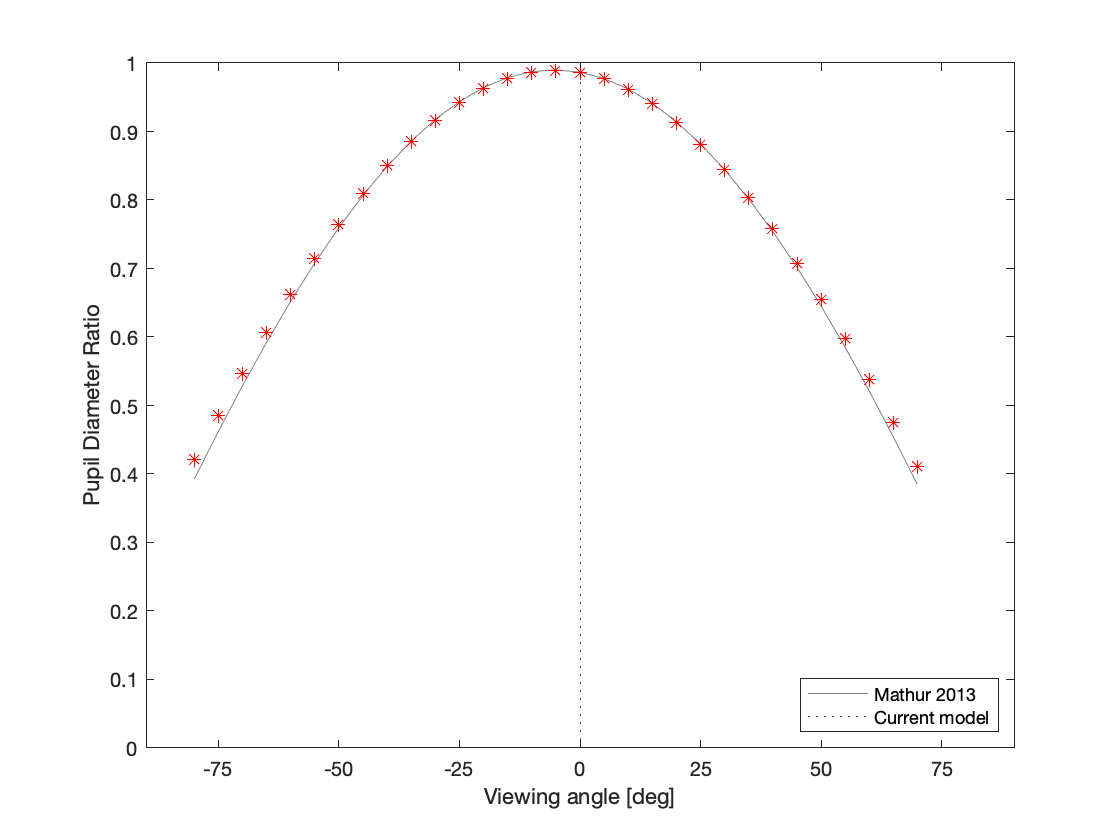

hold on
plot(viewingAngleDeg,diamRatio,'*','Color',[1 0 0]);
legend({'Mathur 2013','Current model'},'Location','southeast');
hold off

The agreement between the empirical measurement and modeled result is quite good. The peak of the function is shifted away from a viewing angle of zero due to the misalignement of the optical (longitudinal) axis of the eye, and the line-of-sight axis. Note that the PDR never reaches unity. This indicates that the pupil is never perfectly circular, and results from a slight ellipticity of the aperture stop. The model over-estimates the PDR at extreme viewing angles. This may be due to a departure of the cornea from a strictly ellipsoidal form far from the apex.